theta = 0:1:179;

% 计算 Radon 变换（假设旋转中心和初始角度未知）
F2 = iradon(File2, theta, 'linear', 'Ram-Lak', 1, 512);
I = imresize(F2,0.5);
I1 = File1;
R = radon(I1);
% 定义目标函数，用于优化旋转中心和初始角度
function error = objective_function(params, I, R, theta)
    % 提取参数
    cx = params(1);
    cy = params(2);
    initial_angle = params(3);
    
    % 平移图像，使得旋转中心与图像中心对齐
    translation = [cx, cy] - size(I) / 2;
    tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
    I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));
    
    % 旋转图像，使得初始角度为 0
    I_rotated = imrotate(I_translated, -initial_angle, 'bilinear', 'crop');
    
    % 计算 Radon 变换
    R_estimated = radon(I_rotated, theta);
    % R_estimated(end+1,:) = ones(1,180);
    % 计算误差
    error = norm(R - R_estimated, 'fro');
end

% 初始猜测参数 [cx, cy, initial_angle]
% initial_params = [size(I, 2) / 2, size(I, 1) / 2, 0];
initial_params = [121,106.89, -28.21];

% 优化参数
options = optimset('Display', 'iter', 'TolFun', 1e-6, 'TolX', 1e-6);
optimized_params = fminsearch(@(params) objective_function(params, I, R, theta), initial_params, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1          11058.3         
     1            4          11058.3         initial simplex
     2            6          11058.3         contract outside
     3            8          11057.1         contract inside
     4            9          11057.1         reflect
     5           11          11056.4         contract inside
     6           13          11056.4         contract inside
     7           15          11056.4         contract outside
     8           17          11056.4         contract inside
     9           19          11056.4         contract inside
    10           21          11056.3         reflect
    11           23          11056.3         contract inside
    12           25          11056.3         contract inside
    13           26          11056.3         reflect
    14           28          11056.3         contract inside
    15           30          11056.3         contract inside
    


% 提取优化后的参数
estimated_center_x = optimized_params(1);
estimated_center_y = optimized_params(2);
estimated_initial_angle = optimized_params(3);

% 打印结果
fprintf('估计的旋转中心: (%.2f, %.2f)\n', estimated_center_x, estimated_center_y);

估计的旋转中心: (119.50, 109.08)


fprintf('估计的初始旋转角度: %.2f 度\n', estimated_initial_angle);

估计的初始旋转角度: -28.07 度


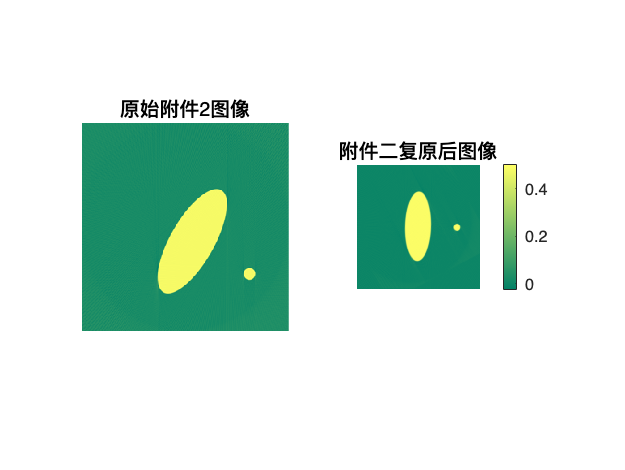


% 使用估计的旋转中心和初始角度进行逆 Radon 变换
% 平移图像，使得旋转中心与图像中心对齐
translation = [estimated_center_x, estimated_center_y] - size(I) / 2;
tform = affine2d([1 0 0; 0 1 0; translation(1) translation(2) 1]);
I_translated = imwarp(I, tform, 'OutputView', imref2d(size(I)));

% 旋转图像，使得初始角度为 0
I_rotated = imrotate(I_translated, -estimated_initial_angle, 'bilinear', 'crop');

% 计算 Radon 变换
R_estimated = radon(I_rotated, theta);

% 使用逆 Radon 变换复原图像
I_reconstructed = iradon(R_estimated, theta);

% 绘制原始图像和复原图像
figure;
subplot(1,2,1);
imshow(I, []);
title('原始附件2图像');

subplot(1,2,2);
imshow(I_reconstructed, []);
title('附件二复原后图像');

colormap("summer")
colorbar